% Output img and make masked image from WarpedTiff for CR_ApplyWarpMatrix.mlx written by NY

Initial = 'KM'; 
Animal = 'tlx49'; 
Date = '231126';
totalBlock = 4;
pixel = 512;
working_directory = '/home/naohiro/Desktop/Yoshida_analysis/Wide-field-calcium-imaging/';

% output session averaged image to specify bregma
cd ([working_directory Date filesep Initial '_' Animal filesep 'WarpedTiff' filesep]);
load([Initial '_' Animal '_WarpedTiff'],'Tiff_Ave','Tiff_Ave_Resize','tformSimilarity','movingRegisteredSmilarity','-mat');
for i = 1:size(Tiff_Ave,3)
    imwrite(uint16(Tiff_Ave(:,:,i)),sprintf('Tiff_Ave_%d.png', i)); %'Tiff_Ave_' i '.tif' )
% imwrite(uint16(Tiff_Ave_Resize(:,:,i)),sprintf('Tiff_Ave_Resize_%d.png', i)) 
end

% make masked image
% 
% threshold = 2000
% 
% cd ([working_directory Date filesep Initial '_' Animal filesep 'WarpedTiff\']);
% load([Initial '_' Animal '_WarpedTiff'],'Tiff_Ave','Tiff_Ave_Resize','tformSimilarity','movingRegisteredSmilarity','-mat');
% 
% clear Tiff_Ave_mask Tiff_Ave_under Tiff_Ave_above
% Tiff_Ave_under = find(Tiff_Ave < threshold);
% Tiff_Ave_above = find(Tiff_Ave >= threshold);
% Tiff_Ave_mask(Tiff_Ave_under) = 1;
% Tiff_Ave_mask(Tiff_Ave_above) = 0;
% Tiff_Ave_mask = reshape(Tiff_Ave_mask, [pixel,pixel,Block])
% 
% imshow(Tiff_Ave_mask(:,:,1))

% adjust threshold until masked image capture imaging region
threshold = 200

threshold = 200

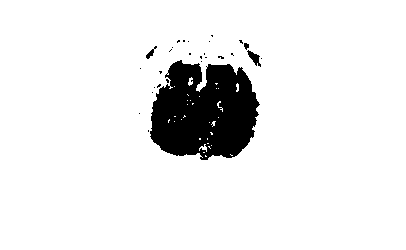

% make masked image
cd ([working_directory Date filesep Initial '_' Animal filesep 'WarpedTiff' filesep]);
load([Initial '_' Animal '_WarpedTiff'],'Tiff_Ave','Tiff_Ave_Resize','tformSimilarity','movingRegisteredSmilarity','-mat');

clear Tiff_Ave_Resize_mask Tiff_Ave_Resize_under Tiff_Ave_Resize_above
Tiff_Ave_Resize_under = find(Tiff_Ave_Resize < threshold);
Tiff_Ave_Resize_above = find(Tiff_Ave_Resize >= threshold);
Tiff_Ave_Resize_mask(Tiff_Ave_Resize_under) = 1;
Tiff_Ave_Resize_mask(Tiff_Ave_Resize_above) = 0;
Tiff_Ave_Resize_mask = reshape(Tiff_Ave_Resize_mask, [128,128,totalBlock]);

imshow(Tiff_Ave_Resize_mask(:,:,1));

save([Initial '_' Animal '_mask_th' num2str(threshold)],'Tiff_Ave_Resize_mask'); %'Tiff_Ave_mask','Tiff_Ave_Resize_mask');